% Parameters
T = 100; % Number of time points
numStates = 5; % Number of state variables
numObs = 2; % Number of observed variables
numErrors = 3; % Number of error variables
phi = 0.5

phi = 0.5000

psi = 0.1

psi = 0.1000

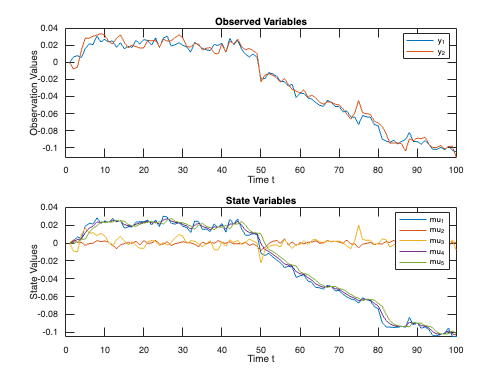


% Initialize variables
mu = zeros(numStates, T); % State variables over time
y = zeros(numObs, T); % Observation variables over time

% Model parameters
A = [1 zeros(1,4); zeros(2,1) diag([psi, phi]) zeros(2,2);...
    zeros(2,3) [1+phi -phi; 1 0]]; % State transition matrix
C = [1 1 0 0 0; 0 0 1 1 0]; % Observation matrix
sigma_eta = [eye(2) zeros(2,1);zeros(1,2) 1;...
    1-phi 0 0;zeros(1,3)]; % Standard deviation matrix for error selection
ft = zeros(numErrors, T); % Dynamic std over time
rhot = zeros(1, T); 

% Constants for dynamics of ft (customize these for different scenarios)
a = {[0.005, 0.002, 0.004]', [0.005 0.002, 0.004]', [0.005, 0.002, 0.004]', [0.005, 0.002, 0.004]'}; % Base levels for each case
b = {[]', [0.02, 0.006, 0.014]', [0.02, 0.006, 0.014]',[0.9, 0.9, 0.9]'}; % Modulation amplitudes
c = {[]', []', [0.01, 0.003, 0.007]',[1e-5, 2e-5, 2e-5]'}; % Additional parameters
da = {0, 0, 0, 0};
db = {[], 0.1, 0.1, 0.5};
dc = {[], [], -0.1, 0.5};

tau1 = 50; % Threshold for single step
tau2 = 75; % Second threshold for double step

% Choose the case here (1 to 6)
case_num = 3;

% Define ft based on the selected case
for t = 1:T
    switch case_num
        case 1 % CONSTANT
            ft(:, t) = a{1};
            rhot(:,t) = da{1};
        case 2 % SINGLE SHOCK
            ft(:, t) = a{2} + b{2} * (t == tau1);
            rhot(:,t) = da{2} + db{2} * (t == tau1);
        case 3 % DOUBLE SHOCK
            ft(:, t) = a{3} + b{3} * (t == tau1) + c{3} * (t == tau2);
            rhot(:,t) = da{3}+db{3}*(t==tau1)+dc{3}*(t==tau2);
        case 4 % AR(1) MODEL
            if t == 1
                ft(:, t) = a{4};
                rhot(:,t) = da{4};
            else
                xi_t = diag(c{4}) * randn(numErrors, 1); % AR(1) noise component
                ft(:, t) = a{4} .* (ones(numErrors,1) - b{4}) + diag(b{4}) * ft(:, t - 1) + xi_t;
                dxi_t = dc{4}*randn(1);
                rhot(:,t) = da{4}*(1-db{4})+db{4}*rhot(:,t-1)+dxi_t;
            end
    end
end

rhot = tanh(rhot);
sigma_alpha = cell(T,1);
for i=1:T
    sigma_alpha{i} = diag(ft(:, i))*[1,0,0;0,1,rhot(i);0,rhot(i),1]*diag(ft(:, i));
end

% Initial state
mu(:, 1) = zeros(numStates, 1); % Random initial state

% Simulation
y(:, 1) = C * mu(:, 1); % Final observation
for t = 2:T
    u_t = sigma_eta * (mvnrnd(zeros(1,3), sigma_alpha{t}, 1)'); % Multivariate noise for state update
    mu(:, t) = A * mu(:, t-1) + u_t; % State update equation
    y(:, t) = C * mu(:, t); % Observation equation
end

% Plotting
figure;
subplot(2,1,1);
plot(1:T, y');
title('Observed Variables');
legend('y_1', 'y_2');
xlabel('Time t');
ylabel('Observation Values');

subplot(2,1,2);
plot(1:T, mu');
title('State Variables');
legend('mu_1', 'mu_2', 'mu_3', 'mu_4', 'mu_5');
xlabel('Time t');
ylabel('State Values');



%{
pxnavextracted.price2 = pxnavextracted.price.^2
reset(groot);
figure;
clf;
plot(pxnavextracted.date, pxnavextracted.price2');
title('price2');
xlabel('Time t');
ylabel('price2');
%}


%{
isin_list = unique(pxnav.isin);
px_nav.lp = log(px_nav.price)

for i = 1:length(isin_list)
    figure; % Create a new figure for each category
    hold on;
    isinData = px_nav(px_nav.isin == isin_list(i), :);
    plot(px_nav.Date, categoryData.Price1, 'b', 'DisplayName', 'Price1');
    plot(categoryData.Date, categoryData.Price2, 'r', 'DisplayName', 'Price2');
    plot(categoryData.Date, categoryData.Price3, 'g', 'DisplayName', 'Price3');
    title(['Category ' uniqueCategories(i)]);
    xlabel('Date');
    ylabel('Price');
    legend show;
    hold off;
end
%}

